# Case 3: 

# Brain self-regulation factorial model 

# with **50** hidden states

## This is the Active Inference case of brain self-regulation learning:  A two-layer that act, infere and learn into a 1 hidden states factor 

## and have communication to solve the uncertainty onto the environmental observations

## The learning process is over the prior transition mappings of the 1st layer

#### In the first layer we design the 'thermometer' mapping between brain states and thermometer observations.

The layer is characterized by having a factor that corrresponds with the activity of teh target area which is the mapping of 2 states corresponds to 'Up' and 'Down observations. However, the mapping between the other states corresponds to a noisy baseline observation; also, the transition between those states are random. 

#### We also add second factor:

####  We design the top-down control between higher levels and the target level. 


close all
clear all
cd

C:\Users\gadri\spm12\toolbox\DEM\GVG_and_tutorial_pomdp\Supplementary code\GVG_DEM\hierarchical\Thesis\Model_3



rng('shuffle'); 

#### Hyperparameters to play with


pr1     =   0.1; % a - precision (inverse termperature) parameter (lower = less precise)

%%%% D-map -  modify the level of confidence in the beliefs: {up, down, left, right}
conf1   =   0.1; 
notconf = 1- conf1; 

%%%% C-map - Parameters that represent avoidance and preference observations 
avoid = - 10; % Location
prefr = 10;  % Location

compl= 10; % C compliance
uncompl = -10; % C compliance

%%%% Learning Rate
eta = 0.6; 

#### Time   

T_1 =  10;   % Times steps in a trial
total_trainig = 36; % Numbers of trials
time = (['t' num2str(T_1) 'x' num2str(total_trainig) ]);

#### Numbers of states, observations  and actions

Here we have 1 hidden state factor: The dimentions of the SMA 

and we have 1 outcome factor : The observed location in the thermometer 

and we have 1 action factor: The actions over the 1st level

% 1st factor {SMA-Thermometer}
ns1 = 50; %number of state 1st factor: location {up, down, left, right}
no1 = 3; % number of observations 1st factor: thermometer {up, down, baseline}
action1 = ns1; % number of action 1st factor: {up, down, let, right}
% 2nd factor {Top-down report}: 
no2 = 2; % number of observations 2nd factor {'ok, not ok'}
ns2 = 2; % number of state 2nd factor {'Good, Bad'}

NO1 = [no1 no2];
n_outcomes = numel(NO1);

## We start building the POMDP

#### Prior beliefs about initial states

D{1} = ones(ns1 , 1)/ ns1; %  1st factor location {up, down, left, right}
D{2} = ones(ns2, 1)/ns2;  % 2nd factor {Top-down report}: 'ok, not ok'

Number of states in each state factor

Ns = [length(D{1}) length(D{2}) ];  %number of states per modality
Nf1 = numel(D); % Number of state factors

#### Probabilistic (likelihood) mapping from hidden states to outcomes - A map

Here we define the value per states according to the total number of states

flat1 = 1 / ns1; % Flat probability Observation 1: between states when are observed as baseline
certainstate = 1-flat1;
unceratinstate = ((flat1*ns1)- (2*flat1));

Here we define the dimentions of the A-map. The rows are the outcomes, and the columns are the alternative levels of the first hidden state factor.

for o = 1:n_outcomes 
    A{o} = zeros([NO1(o), Ns]); % Observations x States of 1st factor x States of 2nd factor
end 

Likelihood mapping of the thermometer with the interaction of the Top-down report

Here we define the likelihood matrix, with high certainty oof states when ti is observed the  'up' and 'down' observation, but uncertainti when it is observe a baseline

for i = 1:Ns(2)
    A{1}(1,1,i) = certainstate; %Up
    A{1}(2, 2, i) = certainstate; % Down
    A{1}(3, 1:2, i) = flat1; % Not-Baseline
    A{1}(3, 3:end, i) = 1; % Baseline
end

Likelihood mapping of the Top-down report  with the interaction of the thermometer

%%%% Good modality
A{2}(2, 3:end,1) = 1;
A{2}(1, 1:2,1) = 1;

%%%% Bad Modality
A{2}(2, 1:2,2) = 1;
A{2}(1, 3:end,2) = 1;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for o = 1:n_outcomes 
    A{o} = double(A{o}); % can be read
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

#### Transition between states -  B map

The rows are the states in current time $s_{t+1}$ , columns are the states in the previous time $s_{t}$, and the 3d position are the allowable actions.

Here we have the total possible transitions between all the states between the thermometer 

B{1}= zeros(Ns(1), Ns(1), action1); 

for i = 1:Ns(1)
    B{1}(i,:,i) = 1; 
end


Here the transitions between the Top-down states

B{2} = zeros(Ns(2), Ns(2), Ns(2)); %s',s, a

B{2}(1,:,1) = 1; % COMPLIANT
% B{2}(2,2,1) = 1; % COMPLIANT

B{2}(2,:,2) = 1; % NOT COMPLIANT

#### Learning the state transition - b learning

b   =      B;

for i = 1:Ns(1)
 b{1}(:,:,i) = rand(Ns(1)); 
end

b{1} = spm_softmax( pr1 * log( b{1} + exp(-4) )); % noise with pr1


#### Prior preferences over the outcomes - C map

Columns correspond to different time steps.

Here we have the preferences of observe 'Up', a strong avoidance to  observe 'Down', and avoidance to observe 'Baseline'

C{1} = zeros(no1, T_1);
C{1}(1,:) = prefr;  % Up 
C{1}(2,:) = avoid; % Down
C{1}(3,:) = 0; %Baselines

And the avoidance to be in the bad state and preference to be in the good state

C{2} = zeros(no2, T_1);
C{2}(1,:) = compl;
C{2}(2,:) = 1-compl;

#### Policies

The rows are the alternative policies 

the columns are the hidden states factors, 

Here we have 1 policy that comprehen the 4 possible transitions

Np1 = [(Ns(1)) (Ns(2))]; % Number of policies

U   = ones(1,Np1(1),Nf1);

%U(:,:,1) = [1 2 3 4]; % 

U(:,:,1) = linspace(1,Ns(1),Ns(1)); % 

%U(:,:,2) = [1 2 1 2]; % E
u2_1 = linspace(1,1,Ns(1)/2);
u2_2 = linspace(2,2,Ns(1)/2);

U(:,:,2) = [u2_1  u2_2];

### POMDP structure

mdp_1.T = T_1;                    % number of updates / time steps
mdp_1.A = A;                      % likelihood mapping
mdp_1.B = B;                      % prior transition probabilities
mdp_1.D = D;                      % prior over initial states
mdp_1.C = C;                      % prior preferred states
mdp_1.U = U;                      % action/policies
% Hyperparameters
mdp_1.erp = 1;                  % degree of belief resetting at each timestep 
                                % or reset the posterior over states. default=1, no decay

% learning:
mdp_1.eta = eta;                 % learning rate
mdp_1.b = b;



#### Labels

label.factor{1}   = 'Location ';   
label.name{1}    = {'1', '2', '3', '4', '5->'};
label.modality{1} = 'Thermometer ';  
label.outcome{1} = {'Up', 'Down', 'Flat'};
label.action{1,1} = {'Regulate','Down Regulate','Baseline','Baseline'};

label.factor{2}   = 'Top-Down';     
label.name{2}    = {'ok','not ok'};
label.modality{2} = 'Modality';  
label.outcome{2} = {'Yes','No'};
label.action{1,2} = {'C', 'Not-C'};



mdp_1.label = label;

### CHECK

MDP_1 = spm_MDP_check(mdp_1);

### Solver: Invert and plot 1st level

MDPlo = spm_MDP_VB_X_tutorial(MDP_1); 

#### PLOTS

% spm_figure('GetWin','Figure 1'); clf    % display behavior
% spm_MDP_VB_trial(MDPlo); 

#### Let's check during more trials . . . 

MDP = spm_MDP_VB_X_tutorial(MDP_1); % Recall POMDP structure
N = total_trainig; % add number of trials
MDP = mdp_1; % use structure
[MDPlo10(1:N)] = deal(MDP); 
MDPlo10 = spm_MDP_VB_X_tutorial(MDPlo10); % Solver

% spm_figure('GetWin','Figure 1'); clf    % display behavior
% spm_MDP_VB_LFP(MDPlo); 
% spm_figure('GetWin','Figure 2'); clf    % display behavior
% spm_MDP_VB_trial(MDPlo10(1), 1:2,1);

#### ... with better plots

### Inference

MDP=MDPlo10;
thesis_tutorial_observationsplots

### Actions

thesis_tutorial_actionandselection

thesis_learning

### Clear for 2nd level construction

clear mdp_1 A B b C D U V MDP

# Second level definition

## Add a 2nd level means add a hierarchical constraints to subordinates states

#### Time

T_2 = 6; 

#### Hyperparameters

pref2 = 10;
brain = 0.2;
target= 1 - brain;

## Numbers of states, observations  and actions

states_lev1= 2;
 % the states from level 1  ACA = 4 NO 2
obs_level2 =  size(MDP_1.A{1},2);
obs_feedback = 3; %% STIMULI 

## We start building the POMDP of the 2nd level

### Prior beliefs about initial states

D2{1} = [ones(obs_level2,1)]; % Observation of level 1 = States level 2
D2{2} = [ 1:T_2 ]'; % Time in trial = 2
D2{3} = [0 0 0]'; % Report: {Up, Down, Baseline} %

#### Number of states per factor

Ns2 = [length(D2{1}), length(D2{2}), length(D2{3}) ]; 

### Probabilistic (likelihood) mapping from hidden states to outcomes - A map

Stimuli

% % Outcomes:  
% % A{1} Stimuli (N, depending of number of observations in level 1) 
% % A{2} Feedback (3: null, ok, notok)



% 
% % States: 9 | Observations: obs_level2 % Observations x States of 1st factor
% 
% % A2{1} = zeros(obs_level2, State level 2, Time, Report);
A2{1} = zeros(obs_level2, length(D2{1}), length(D2{2}), length(D2{3}) );%
% 
% 
%  % state                       | observation
for i = 1:length(D2{2})
    for j = 1: length(D2{3})
        A2{1,1}(:,:,i,j) = eye(obs_level2);
    end
end

Feedback

% Sates: 1, 2, 3 ...N   | Observations: Up, Down, Baseline
A2{2} = zeros(obs_feedback, length(D2{1}), length(D2{2}), length(D2{3}) );
% A2{1} = zeros( obs_level2, obs_feedback, Time, Report); 


%--- Es lo que CATEGORIZO
 % state: 1, 2, 3, ...N   | observation: Up, Down, Baseline

A2{1,2}(1,1,:, 1 ) = 1;
flatup= 1/ 3;
A2{1,2}(1:end,2:end,:, 1 ) =  flatup;


A2{1,2}(2,2,:, 2 ) = 1;
flatdown= 1/ 3;
A2{1,2}(1:end,3:end,:, 2 ) = flatdown;
A2{1,2}(:,1,:, 2 ) = flatdown;


A2{1,2}(3:end, 3:end, :, 3 ) = 1;
flatbaseline= 1/ 3;
A2{1,2}(1:end, 1:2, :, 3 ) = flatbaseline;

### Learning the likelihood - a learning

a2 = A2; % likelihood (concentration parameters) for generative model
% reduce precision
pr2 = 2; % precision (inverse termperature) parameter (lower = less precise)

for i = 1:T_2
   for j= 1:size(A2{1},1)
     a2{1}(:,:,i,j) = rand(obs_level2, obs_level2); %try eye or rand
    end
end
a2{1} = spm_softmax(pr2 * log(A2{1} + exp(-4))) ;

a2{1} = a2{1}*10;
a2{2} = a2{2}*10;

### Transition between states -  B map

action2_s1 = 3;
action2_s3 = 3; % number of action 3d factor: {null, control, notcontrol}

% Sequence mapping VARIABLE
% (i.e., the sequence is stable within a trial)
% Observation of level 1 = States level 2
B2{1} = zeros(Ns2(1), Ns2(1), action2_s1); 

for i = 1:size(B2{1},3)
    B2{1}(:,:,i)= eye(Ns2(1), Ns2(1));

end

% TIME 
% Deterministically transition through trial sequence
B2{2} = zeros(Ns2(2),Ns2(2));

for i = 1:(size(B2{2},1)-1)
    B2{2}(i+1,i) =  1;
end
B2{2}(end, end) = 1;
     
% REPORT
% Controlable behavior state

B2{3}= zeros(Ns2(3), Ns2(3), action2_s3); %s',s, a
% 
B2{3}(1,:,1) = 1;
%                 [1 1 1;
%                 0 0 0;
%                 0 0 0]; % Pre-report 

B2{3}(2,:,2) = 1;
%                 [0 0 0;
%                 1 1 1;
%                 0 0 0]; % Report "control"

B2{3}(3,:,3) = 1;
%                 [0 0 0;
%                 0 0 0;
%                 1 1 1]; % Report "notcontrol"
% 

### Policies

T_2 = length(D2{2});  % number of timesteps
Nf_2 = size(Ns2,2); % number of factors
Pi_2 = 3; % number of policies
V2 = ones(T_2-1,Pi_2,Nf_2);

% Report: "same" (left column) or "different" (right column)
V2(end,:,3) = [ 1 2 3];
% V2(:,2,2) = 2;
% V2(:,2,3) = 3;

### Prior preferences over the outcomes - C map

% %--------------------------------------------------------------------------
% % Outcomes:  
% % A{1} Stimuli (N, depending of number of observations in level 1) 
% % A{2} Feedback (3: null, ok, notok)

% Stimuli
C2{1} = zeros( obs_level2, T_2);
C2{1}(1,:) = pref2;
C2{1}(2,:) = - pref2;
C2{1}(3,:) = - pref2/2;


% % Feedback
C2{2} = zeros( obs_feedback, T_2 );
C2{2}(1,end) = 0; % no feedback yet
C2{2}(2,end) = -1; % preference not to be incorrect at last timestep
C2{2}(3,end) = 1;% preference for being correct at last timestep

### Connect lower level states with higher level

mdp.MDP  = MDP_1;

### LINK - subordinate MDP

#### Provide a matrix specifying which outcome modalities at the second level (columns)  corresponds to which state factors at the lower level (rows) within the link field. 

#### Here, the first outcome at the second level (Stimuli)  corresponds to the first state factor at the first level (brain state):

Ng    = numel(A2);
%mdp.link = [1 0]; 
%% S = sparse(i,j,v,m,n) specifies the size of S as m-by-n.
mdp.link = sparse(1,1,1, numel(MDP_1(end).D), Ng);

## POMDP structure 2nd level

mdp.T = T_2;                    % number of time points
mdp.A = A2;                     % likelihood mapping for generative process
mdp.a = a2;                    % likelihood mapping for generative model
mdp.B = B2;                     % transition probabilities
mdp.C = C2;                     % preferred outcomes
mdp.D = D2;                     % priors over initial states for generative process
% mdp.d = d2;                     % priors over initial states for generative model
mdp.V = V2;                     % policies

% Learning
mdp.erp2 = 1;                % reset/decay paramater
mdp.a = a2;                    % generative process

#### Labels

label.factor{1}   = 'Sequence';   label.name{1}    = {'high', 'low', '3', '...'};
label.modality{1} = 'sequence';  label.outcome{1} = {'high', 'low', '3', '...'};

label.factor{2}   = 'Time Trial';   label.name{2}    = {'begin', '1',  'end'};
label.modality{2} = 'time trial';  label.outcome{2} = {'begin', '1',  'end'};

label.factor{3}   = 'Feedback';   label.name{3}    = {'null', 'regulate', 'disregulate'};
label.modality{3} = 'feedback';  label.outcome{3} = {'null', 'regulate', 'disregulate'};


mdp.label = label;

mdp.Aname = {'Stimulus', 'Category'};
mdp.Bname = {'Sequence', 'Time in trial', 'Report'};%

#### CHECK

mdp = spm_MDP_check(mdp);

#### Invert

MDP = spm_MDP_VB_X_tutorial(mdp);

### PLOTS

### Plot one trial

spm_figure('GetWin','trial'); clf
spm_MDP_VB_trial(MDP);

### Let's check during more trials the effect of the 2nd layer. . . 

N = 10; %number of trials
[MDP(1:N)] = deal(MDP); 
MDP = spm_MDP_VB_X_tutorial(MDP); % Solver

## PLOTS

F1 = 1

F2 =      1     2


F3 =      1     2     3


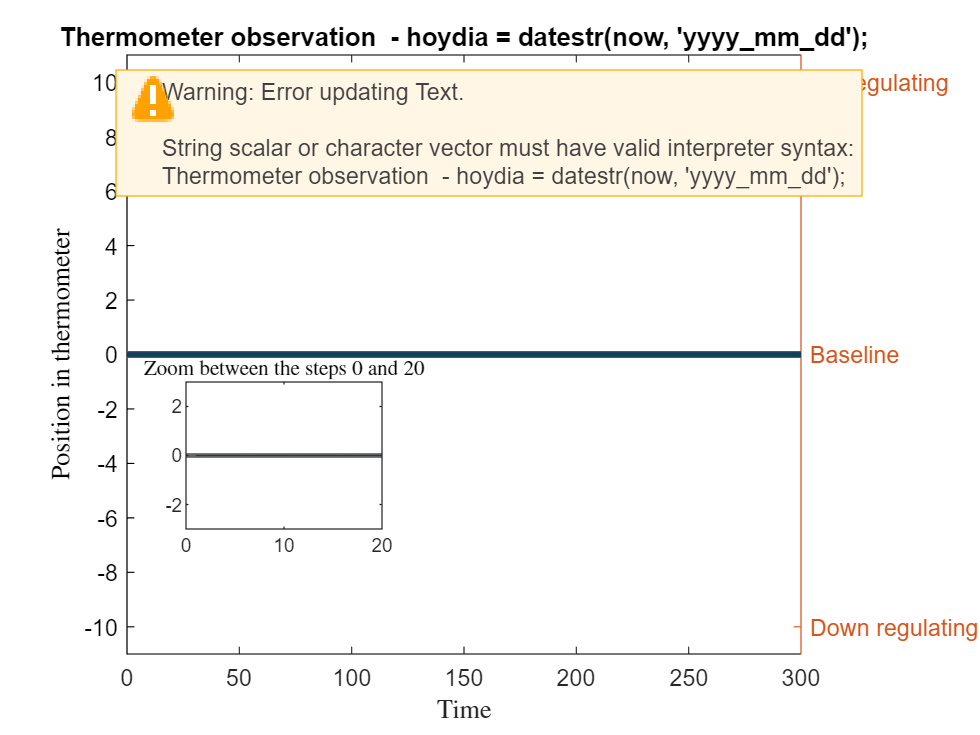

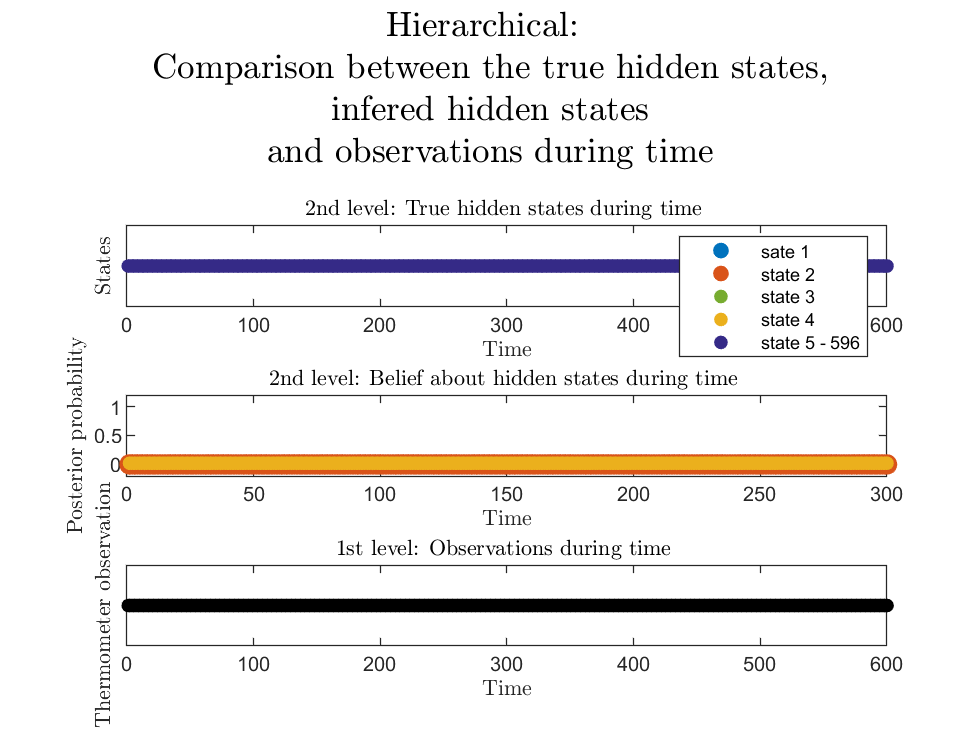

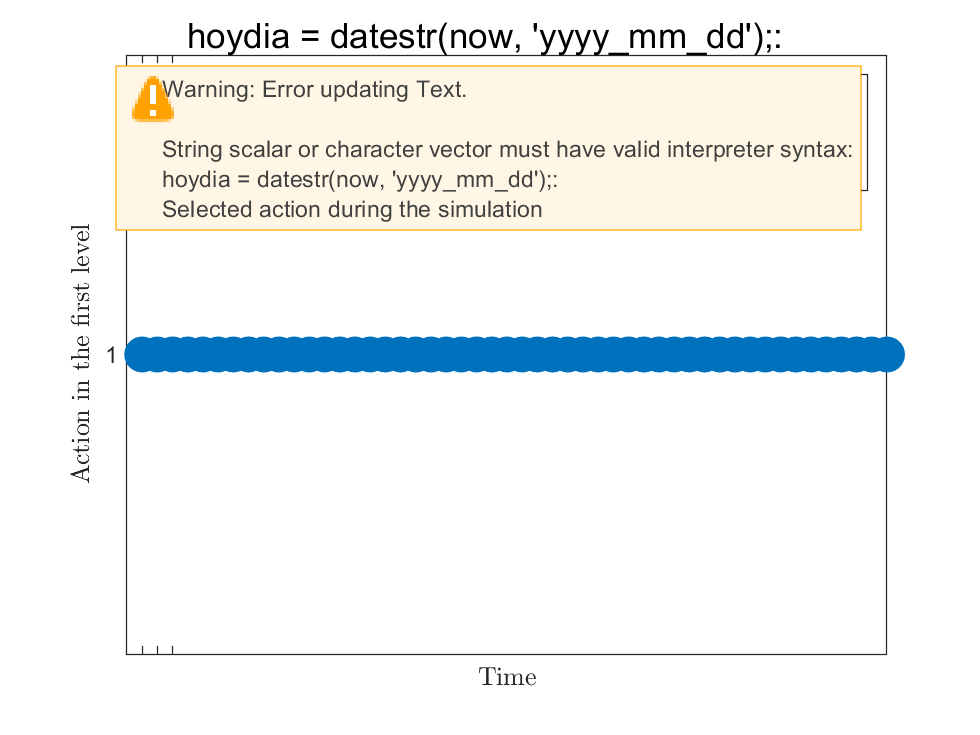

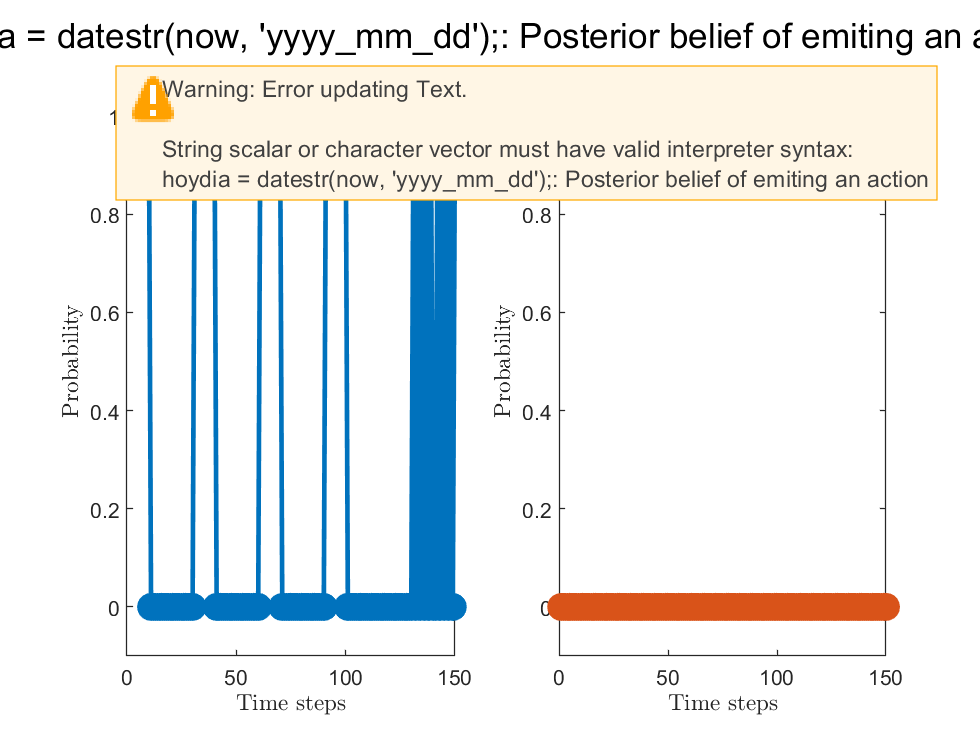

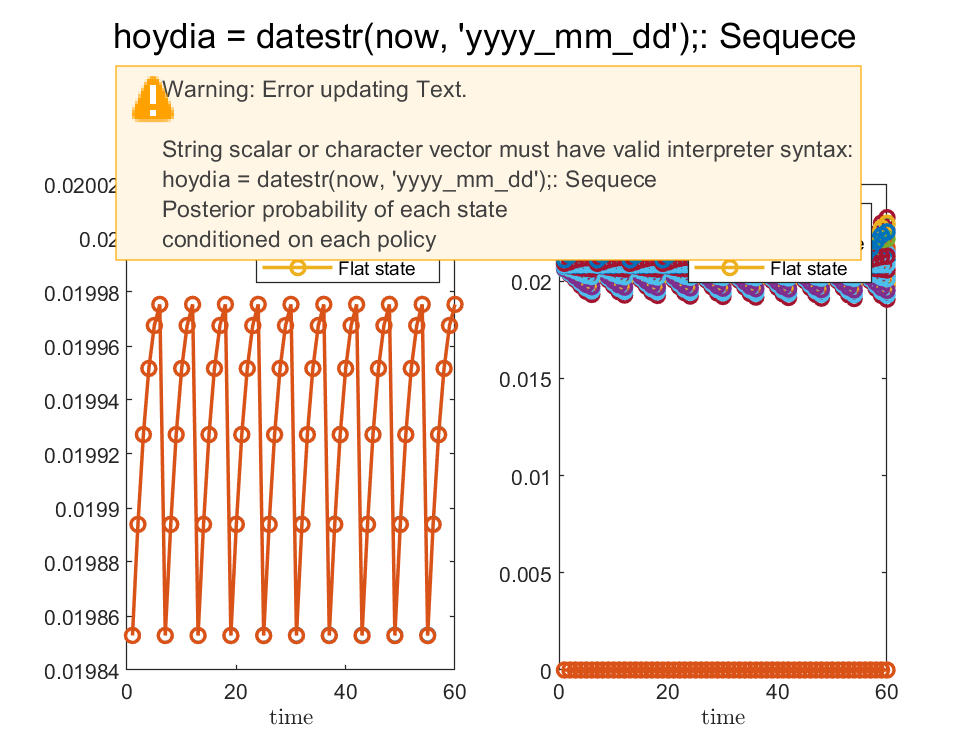

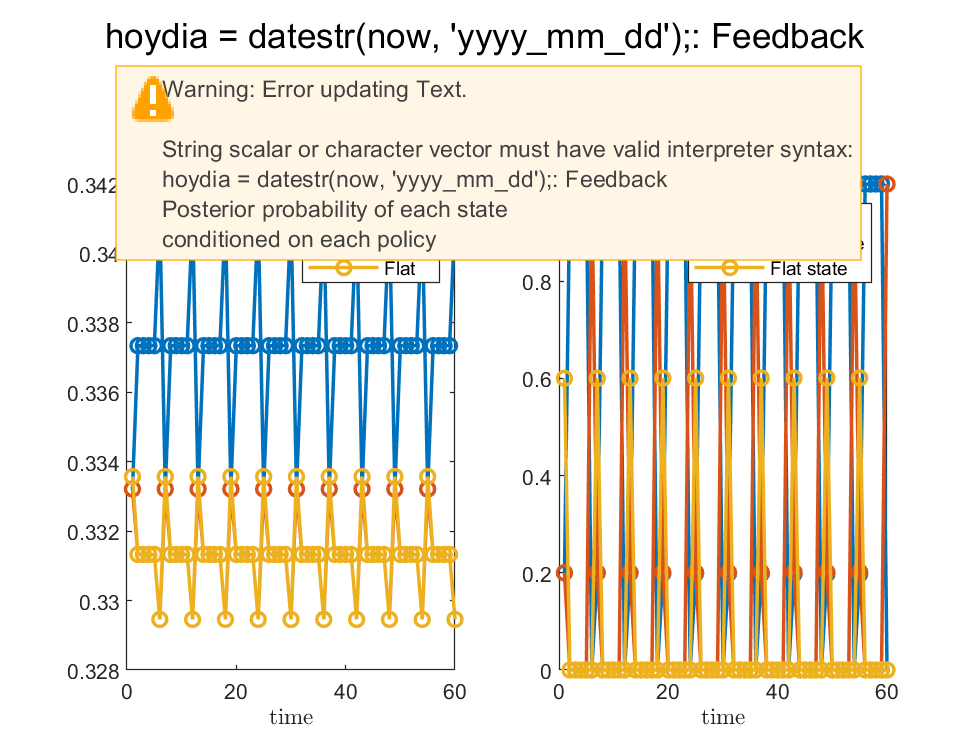

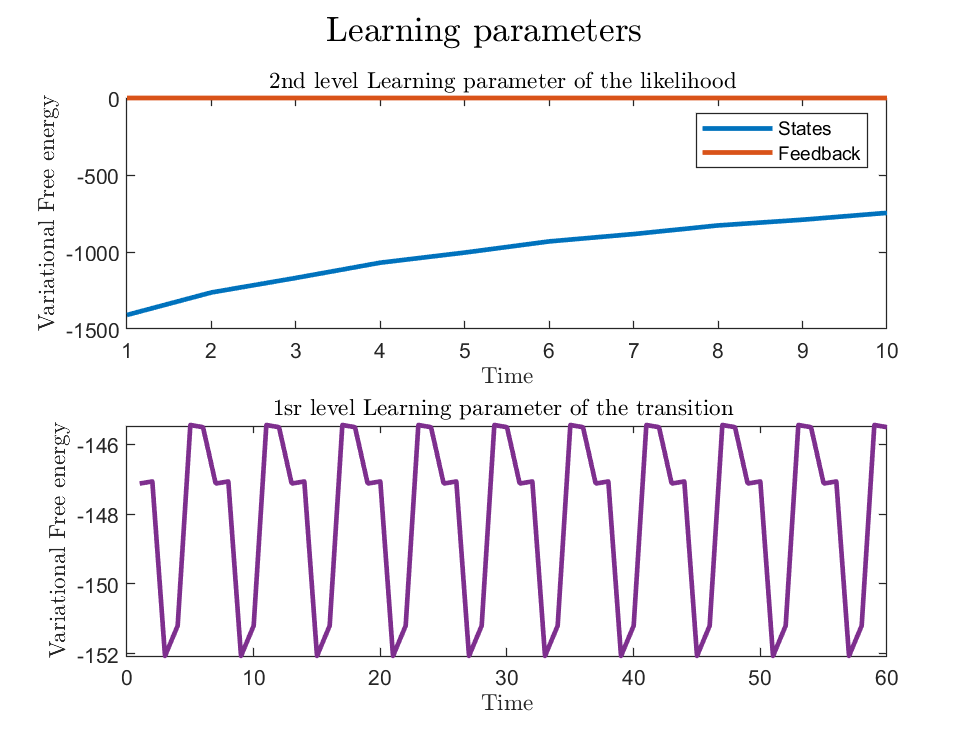

thesis_hierarchical

## SAVE EXPERIMENT

%% SAVE
hoydia = datestr(now, 'yyyy_mm_dd');


% File name - version
filePath = matlab.desktop.editor.getActiveFilename;
numver = size(filePath,2);
version = str2double( cell2mat( extract(filePath ,numver)));
if (version >= 0)
    pass
else 
    version = 1;
end


% % % SPECIFIC FOLDER to save the experiment by name of the experiment
pathname = cd ;
filename = ( [ 'MDP_case3_50hs_' hoydia '_' num2str(time) '.mat'  ] ) ;
% %num2str(varnamesave)  %% AD WHEN YOU HAVE IT
% % If the folder doesn't exist, create it.
% if ~exist(pathname, 'dir')
%    mkdir(pathname );
% end
save( fullfile(pathname, filename), 'MDP'); % SAVE THE OUTPUT IN THE FOLDER

% %%%%%%% ITERATOR FOR SEVERAL MDP'S
